## **Recolección de datos por figura**

%https://la.mathworks.com/help/robotics/ref/importrobot.html
robot = importrobot('manipulator_description/urdf/manipulator.urdf');
robot.DataFormat = 'row';
robot.Gravity = [0 0 -9.81];
joint_data_square =     table2array(readtable(strcat('matlab/joint_goals_square_45.txt')));
joint_data_triangle =   table2array(readtable(strcat('matlab/joint_goals_triangle_45.txt')));
joint_data_circle =     table2array(readtable(strcat('matlab/joint_goals_circle_45.txt')));
joint_data_espol_logo = table2array(readtable(strcat('matlab/joint_goals_espol_logo_45.txt')));
joint_data_espol =      table2array(readtable(strcat('matlab/joint_goals_espol_45.txt')));
 

## Determinantes

for i = 1:length(joint_data_square)
    det_square(i) = det(geometricJacobian(robot,deg2rad(joint_data_square(i,:)),'link_6'));
end
for i = 1:length(joint_data_triangle)
    det_triangle(i) = det(geometricJacobian(robot,deg2rad(joint_data_triangle(i,:)),'link_6'));
end
for i = 1:length(joint_data_circle)
    det_circle(i) = det(geometricJacobian(robot,deg2rad(joint_data_circle(i,:)),'link_6'));
end
for i = 1:length(joint_data_espol_logo)
    det_espol_logo(i) = det(geometricJacobian(robot,deg2rad(joint_data_espol_logo(i,:)),'link_6'));
end
for i = 1:length(joint_data_espol)
    det_espol(i) = det(geometricJacobian(robot,deg2rad(joint_data_espol(i,:)),'link_6'));
end

## Gráficas

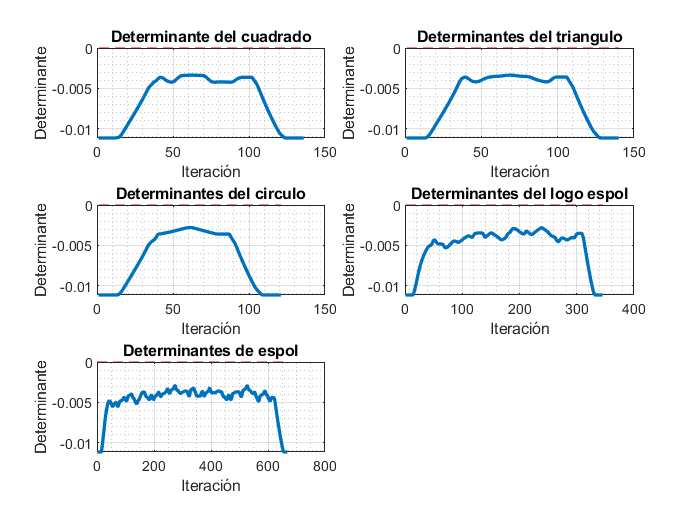

figure(1);

i=1;
subplot(3,2,i)
plot(det_square,"LineWidth",2)
grid on
grid minor
title("Determinante del cuadrado")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(det_square)], [0, 0], 'r--');
i = i+1;

subplot(3,2,i)
plot(det_triangle,"LineWidth",2)
grid on
grid minor
title("Determinantes del triangulo")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(det_triangle)], [0, 0], 'r--');
i = i+1;

subplot(3,2,i)
plot(det_circle,"LineWidth",2)
grid on
grid minor
title("Determinantes del circulo")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(det_circle)], [0, 0], 'r--');
i = i+1;

subplot(3,2,i)
plot(det_espol_logo,"LineWidth",2)
grid on
grid minor
title("Determinantes del logo espol")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(det_espol_logo)], [0, 0], 'r--');
i = i+1;

subplot(3,2,i)
plot(det_espol,"LineWidth",2)
grid on
grid minor
title("Determinantes de espol")
xlabel("Iteración")
ylabel("Determinante")
hold on;
plot([1, length(det_espol)], [0, 0], 'r--');

i = i+1;

